%Basic_initialisation 
bandwidth = 4000;
freq_carrier1= bandwidth*2;
freq_carrier2= bandwidth*8;
Fs=44100;

%AUDIO Capture and read block 

%audio read 

noc= 1;
nob=16;%8,16,24
recObj = audiorecorder(Fs,nob,noc);  
disp("Recording Voice 1 for 3- seconds ");

Recording Voice 1 for 3- seconds 


recordblocking(recObj,3);
s1= getaudiodata(recObj);
longituds1 = length(s1);
disp("Recording Voice 2 for 3- seconds ");

Recording Voice 2 for 3- seconds 


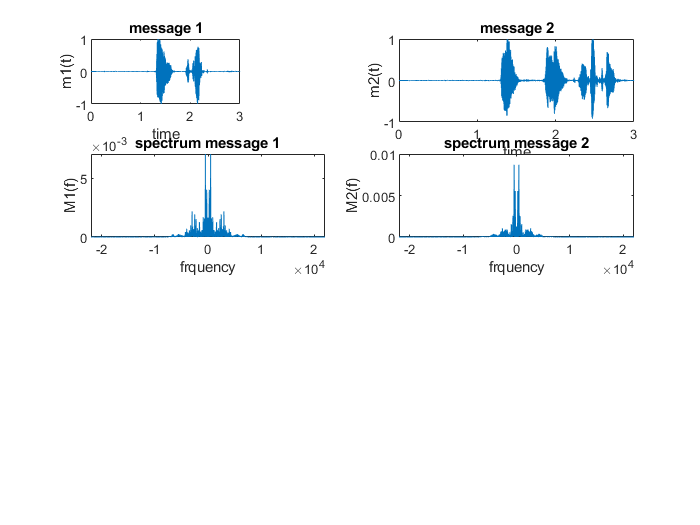

recordblocking(recObj,3);
s2= getaudiodata(recObj);

longituds2 = length(s2);

%truncation_block
longitud_minima = min([longituds1 longituds2]);
t = linspace(0,3,longitud_minima);
s1 = s1(1:longitud_minima);
s2 = s2(1:longitud_minima);

%plotting data signals 
subplot(4,3,1);
plot(t,s1);
title('message 1');
xlabel('time');
ylabel('m1(t)');
subplot(4,2,2);
plot(t,s2);
title('message 2');
xlabel('time');
ylabel('m2(t)')

%fft plotting for visualisation 

N = longitud_minima;
f = Fs*(-N/2:N/2-1)/N;
subplot(4,2,3);
fft_s1= fftshift(fft(s1,N)/N);
plot(f,abs(fft_s1));
title('spectrum message 1');
xlabel('frquency');
ylabel('M1(f)');
subplot(4,2,4);
fft_s2= fftshift(fft(s2,N)/N);
plot(f,abs(fft_s2));
title('spectrum message 2');
xlabel('frquency');
ylabel('M2(f)');

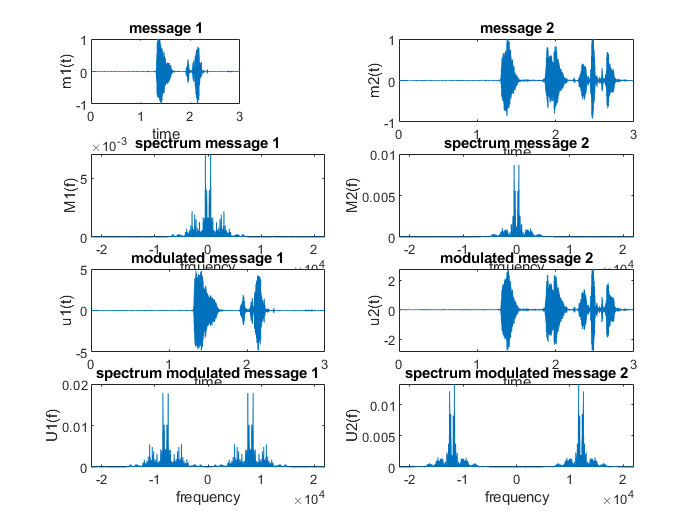

%MODUlATION PART 
c1= 5*cos(2*pi*freq_carrier1*t);
c1=c1';
modsig1=s1.*c1;
subplot(4,2,5);
plot(t,modsig1);
title('modulated message 1');
xlabel('time');
ylabel('u1(t)');
%plotting in time scale 
c2=3*cos(2*pi*freq_carrier2*t);
c2=c2';
modsig2=s2.*c2;
subplot(4,2,6);
plot(t,modsig2);
title('modulated message 2');
xlabel('time');
ylabel('u2(t)');

%fft plotting 
subplot(4,2,7);
fft_mods1= fftshift(fft(modsig1,N)/N);
plot(f,abs(fft_mods1));
title('spectrum modulated message 1');
xlabel('frequency');
ylabel('U1(f)');
subplot(4,2,8);
fft_mods2= fftshift(fft(modsig2,N)/N);
plot(f,abs(fft_mods2));
title('spectrum modulated message 2');
xlabel('frequency');
ylabel('U2(f)');

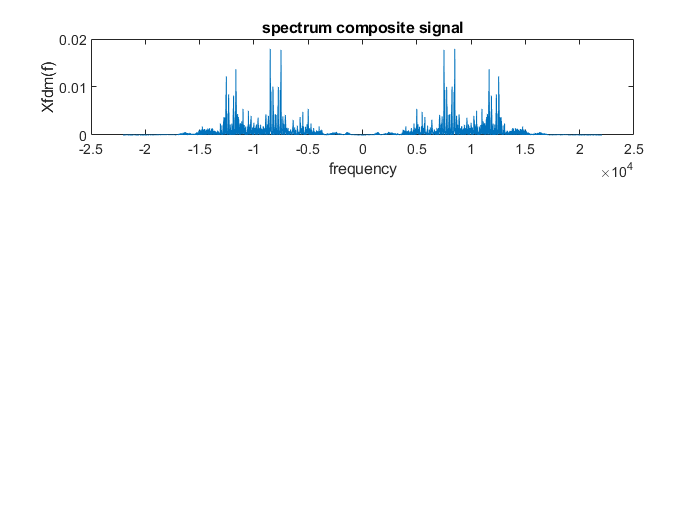

%fdm part 
figure;
net_sig = modsig2+modsig1;
subplot(3,1,1);
fft_netsig= fftshift(fft(net_sig,N)/N);
plot(f,abs(fft_netsig));
title('spectrum composite signal');
xlabel('frequency');
ylabel('Xfdm(f)');

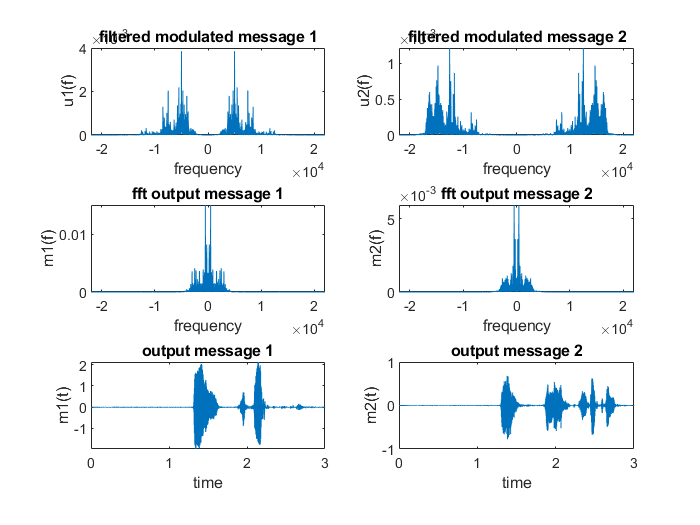

%fitering part 

freq_cutoff = 2000; %audio range is 2500 
[B,A] = butter(4,freq_cutoff/(Fs/2));
pass_band= @(S) filter(B,A,S);

[C1,D1] = butter(2,[freq_carrier1-freq_cutoff freq_carrier1+freq_cutoff]/(Fs));
filter_band1 = @(S) filter(C1,D1,S);
[C2,D2] = butter(2,[freq_carrier2-freq_cutoff freq_carrier2+freq_cutoff]/(Fs));
filter_band2 = @(S) filter(C2,D2,S);

filter_s1 = filter_band1(net_sig);
fft_filter_s1= fftshift(fft(filter_s1,N)/N);
subplot(3,2,1);
plot(f,abs(fft_filter_s1));
title('filtered modulated message 1');
xlabel('frequency');
ylabel('u1(f)');

filter_s2 = filter_band2(net_sig);
fft_filter_s2= fftshift(fft(filter_s2,N)/N);
subplot(3,2,2);
plot(f,abs(fft_filter_s2));
title('filtered modulated message 2');
xlabel('frequency');
ylabel('u2(f)');

%coherent-DSBSC Demodulation 
filter_input1=filter_s1.*c1;
filter_input2=filter_s2.*c2;
%low pass filter
sig1_t=pass_band(filter_input1);
%low pass filter
sig2_t=pass_band(filter_input2);

fft_sig1_t= fftshift(fft(2*sig1_t,N)/N);
fft_sig2_t= fftshift(fft(2*sig2_t,N)/N);
subplot(3,2,3);
plot(f,abs(fft_sig1_t));
title('fft output message 1');
xlabel('frequency');
ylabel('m1(f)');
subplot(3,2,4);
plot(f,abs(fft_sig2_t));
title('fft output message 2');
xlabel('frequency');
ylabel('m2(f)');

subplot(3,2,5);
plot(t,real(2*sig1_t));
title('output message 1');
xlabel('time');
ylabel('m1(t)');
subplot(3,2,6);
plot(t,real(2*sig2_t));
title('output message 2');
xlabel('time');
ylabel('m2(t)');

%final audio replay 
k=5;

while k==5
choice = input("Whose voice you want to extract");
if choice==1
player1 = audioplayer(2*sig1_t,Fs);
playblocking(player1);
end

if choice==2
player2 = audioplayer(2*sig2_t,Fs);
playblocking(player2);
end
k = input("do you want to cotinue? (y=5/n=6)");
end









